# Handwritten Character Recognition Using Neural Networks

This code here is what was later used in GUI To train the neural network EMNIST dataset was used, which can be downloaded from here [<https://www.kaggle.com/crawford/emnist](https://www.kaggle.com/crawford/emnist)>

close all
clear
clc
addpath(genpath('C:\Users\RAHUL AIRAN\Desktop\HandwritingRecognition\testImages'))
% This is the pretrained network, which was trained using "nprtool".
% It was save after training was completed as .mat file.
% During the training 150 neurons in hidden layer were used.
% It just loads the Neural Network in workspace
load('network.mat');

## Input Image

Here input image which is a RGB image is preprocessed, converted to Binary Image, followed by noise removal

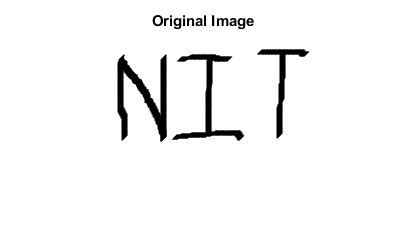

imagePath = fullfile('testImages','nit.png');
originalImage = imread(imagePath);
% Showing Original image˳
% figure(1);
imshow(originalImage);
title('Original Image');

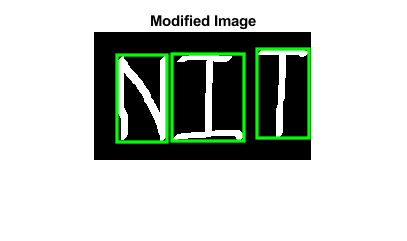

% Conversion to grayScale image
grayImage = rgb2gray(originalImage);
% Conversion to binary image
threshold = graythresh(grayImage);
binaryImage = ~im2bw(grayImage,threshold);
% Removes all object containing fewer than 30 pixels
moddedImage = bwareaopen(binaryImage,30);
pause(1)
% Showing binary image
figure(2);
imshow(moddedImage);
title('Modified Image');
% Labelling connected components
[L,Ne] = bwlabel(moddedImage);
% Measuring properties of image regions
propied = regionprops(L,'BoundingBox');
hold on
% Plot Bounding Box
for n=1:size(propied,1)
    rectangle('Position',propied(n).BoundingBox,'EdgeColor','g','LineWidth',2)
end
hold off

pause (1)

## Image Segmentation

In here each character from the input image is seperated, preprocessed similar to E-MNIST dataset to reduce the error figure(3);

for n=1:Ne
    [r,c] = find(L==n);
    n1 = moddedImage(min(r):max(r),min(c):max(c));
    n1 = imresize(n1,[128 128]);
    n1 = imgaussfilt(double(n1),1);
    n1 = padarray(imresize(n1,[20 20],'bicubic'),[4 4],0,'both');
%     imshow(~n1);
    fullFileName = fullfile('segmentedImages', sprintf('image%d.png', n));
    imwrite(n1, fullFileName);
    pause(1)
end

## Feeding to Neural Network and Detecting Text

for i=1:Ne
    segImage=reshape(double(imread(fullfile('segmentedImages', sprintf('image%d.png', i)))) , 784, 1);
    outputMatrix=net(segImage);
    row=find(ismember(outputMatrix, max(outputMatrix(:)))); % returns the row number which has highest probability
%     figure(i);
%     colormap(gray)
    character = double(imread(fullfile('segmentedImages', sprintf('image%d.png', i))));
%     imagesc(~character)
%     title(imageLabeler(row))
    detectedWord(1,i)=imageLabeler(row);
end

## Displaying Detected Text

fprintf('Detected Text: %s\n',detectedWord)

Detected Text: NIT
